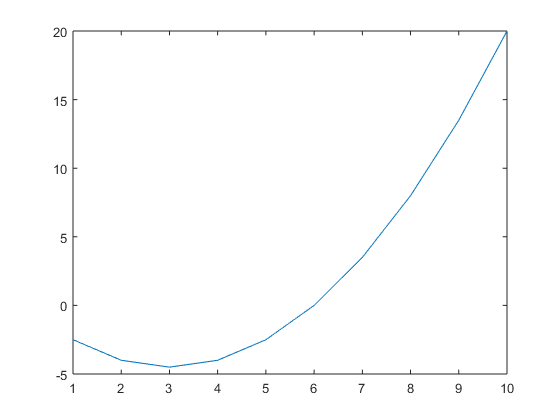

x = (1:1:10).';
y = 0.5*x.^2-3*x;
n = length (x);
sigmaF = 1;%0.3
sigmaN = 1;%0.2
l = 1;%0.7

K =CovMatrix(x,sigmaF,l);

K_inv = chol(K+sigmaN^2*eye(n));
plot(x,y)

logLikelihood_V1(y,K,sigmaN)

ans = -143.4268

xT = 5;
kT = zeros(n,1);
for i = 1: n
    kT(i) = kernel(x(i),xT,1,1);
end
yT = kT.'*K_inv*y

yT = -5.0681

y(xT/1)

ans = -2.5000

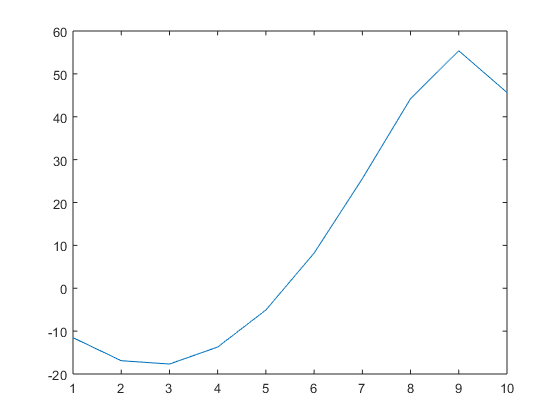

f_mean = K*K_inv*y;
plot(x,f_mean)

[vec,val ]=eig(K);
A = zeros(n);
for i =1:n
    A  = A+ val(i,i)*vec(:,i)*vec(:,i).';
end
g = zeros(n,1);
for i = 1:n
    g(i) = vec(:,i).'*y;
end
f_mean2 = zeros(size(f_mean));
for i = 1:n
    f_mean2 = f_mean2 + g(i)*val(i,i)/(val(i,i)+sigmaN^2)*vec(:,i); 
end
f_mean2

f_mean2 =    -1.7325
   -2.7411
   -3.1160
   -2.7582
   -1.6841
    0.1048
    2.5733
    5.8887
   10.1301
   11.1700


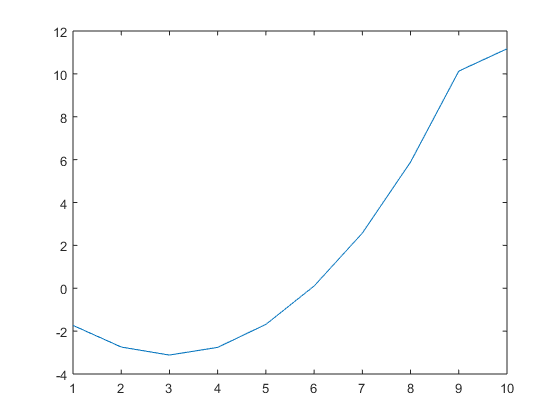

plot(x,f_mean2)